%creating the histogram
c11 = c11(:);
clf;
hold on;
LegHandles = []; LegText = {};
[CdfF,CdfX] = ecdf(c11,'Function','cdf');  
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(c11,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0 0 1],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Counts per Data');
ylabel('Normalized Distribution of Counts')
LegHandles(end+1) = hLine;
LegText{end+1} = 'c11 data';

XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XContinuous = linspace(XLim(1),XLim(2),100);
XIncr = max(1,floor((XLim(2)-XLim(1))/100));
XDiscrete = floor(XLim(1)):XIncr:ceil(XLim(2));
%creating error bars

normalizedelements=[0.005 0.02 0.05 0.125 0.1 0.09 0.05 0.04 0.01 0.01];
elements=200*normalizedelements;
bincenters= 3:2:21;
err=sqrt(elements)/200;
bar(bincenters, normalizedelements);

errorbar(bincenters,normalizedelements, err,'*');
%creating gaussian fit
pd1 = fitdist(c11, 'normal')

pd1 =   NormalDistribution

  Normal distribution
       mu =    10.9   [10.1824, 11.6176]
    sigma = 3.61674   [3.17552, 4.20148]


XGrid = XContinuous;
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 1';
%creating poisson fit
pd2 = fitdist(c11, 'poisson')

pd2 =   PoissonDistribution

  Poisson distribution
    lambda = 10.9   [10.2529, 11.5471]


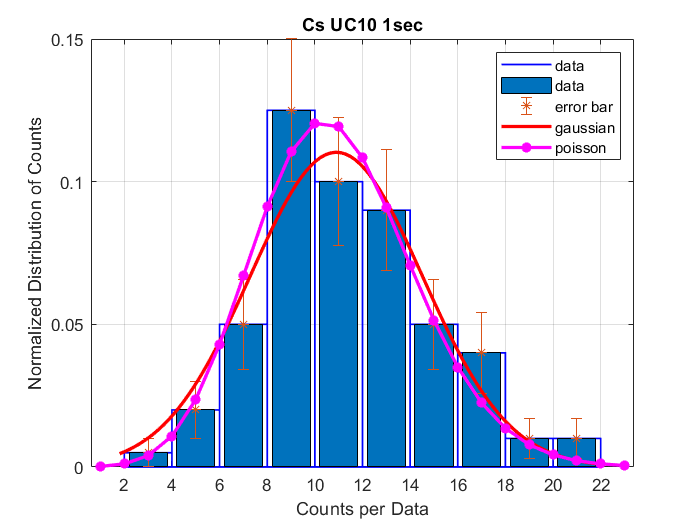

XGrid = XDiscrete;
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 1],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','*', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'fit 2';
legend({'data','gaussian','poisson'})
legend({'data','data','error bar', 'gaussian','poisson'})
box on;
hold off;
grid on

title('Cs UC10 1sec')